## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

**Section 12 - Example 05 - Deploymeng of Miura Origami Unit**

In this example, we will try to simulate the deployment process of a Miura origami unit. Miura origami is one iconic pattern in origami science and engnineering because of its unique kinematics. The following figure defines the geometry of a Miura origami unit. The red bold line is called valley-fold while the blue dotted line is the mountain-fold. A valley fold will fold upward to form a valley shape and the mountain fold will fold downward to form a moutnain shape. 

## 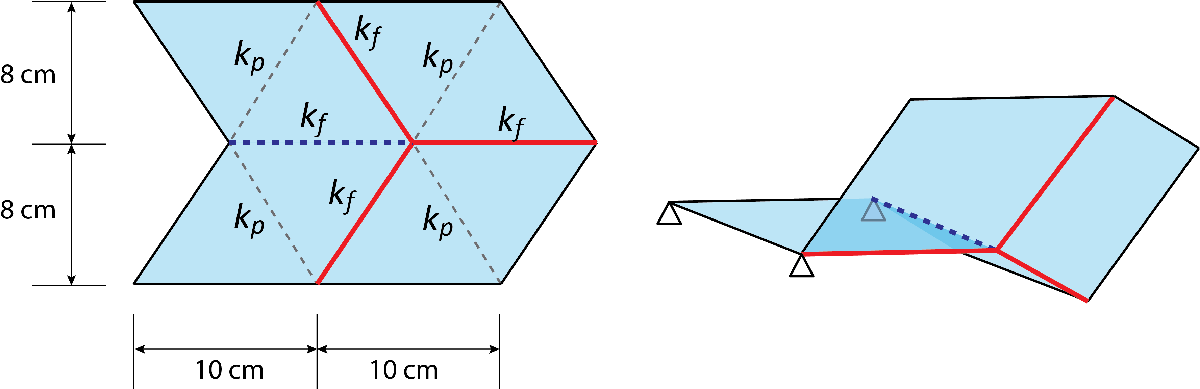

After we clear the memory, we define the mechanical properties of the Miura origami using the following script. We assume that the creases' folding stiffness is $k_f =0\ldotp 00001\frac{N\cdot m}{m}$ and assume the panel bending stiffness is 100 times the folding stiffness so $k_p =0\ldotp 001\frac{N\cdot m}{\;m}$. The materials properties of the panels are also assumed as shown in the code:

clear all;
clc;
close all;

% Define the stiffness parameter of the structure
k_f=0.00001;
k_p=0.001;

% Define the material properties of the panel
panelE=10*10^6;  % Young's modulus 10MPa
panelv=0.3; % Poisson's Ratio 0.3
panelt=1*10^-3; % Thicknes 1mm

After defining the material properties, we further define the object from the class. Here, we will use the constant strain triangle element (cst) to capture the triangle panels in an origami and use the four-node rotational spring element (rotSpr) to capture the panel bending and crease folding. 

% Initialize the class
cst=Vec_Elements_CST;
rotSpr=Vec_Elements_RotSprings_4N;
node=Elements_Nodes;

After defining each object, we set up the assembly as usual.

assembly=Assembly_CST_Origami();
assembly.node=node;
assembly.cst=cst;
assembly.rotSpr=rotSpr;

We next define the geometry of Miura origami. This Miura origami has a total of 9 node and in the flat configuration they are in the XY plane. 

node.coordinates_mat=[0,0,0;
                      0.1,0,0;
                      0.2,0,0; % Node 3
                      0.04,0.08,0;
                      0.14,0.08,0;
                      0.24,0.08,0; % Node 6
                      0,0.16,0;
                      0.1,0.16,0;
                      0.2,0.16,0]; % Node 9

We then set up the ploting function and plot the location of the node of this Miura origami. 

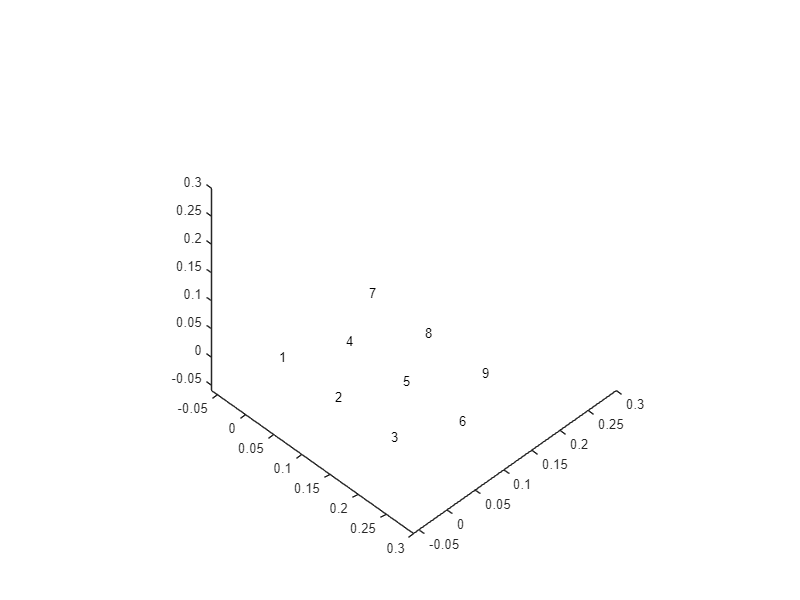

plots=Plot_CST_Origami();
plots.displayRange=0.3;
plots.displayRangeRatio=0.2;
plots.assembly=assembly;

plots.Plot_Shape_NodeNumber()

Everything looks good!

We next set up the panels. Each constant strain triangle element is connecting three node, represented as a row in the "cst_ijk_mat". After defining the connectivity, we define the material properties of these CST elements. The CST element is shown in the following figure. 

% set up panels for plotting
cst.node_ijk_mat=[1 2 4;
                 2 4 5;
                 2 3 5;
                 3 5 6;
                 4 8 7;
                 4 5 8;
                 5 9 8;
                 5 6 9];
cst.v_vec=panelv*ones(8,1);
cst.E_vec=panelE*ones(8,1);
cst.t_vec=panelt*ones(8,1);

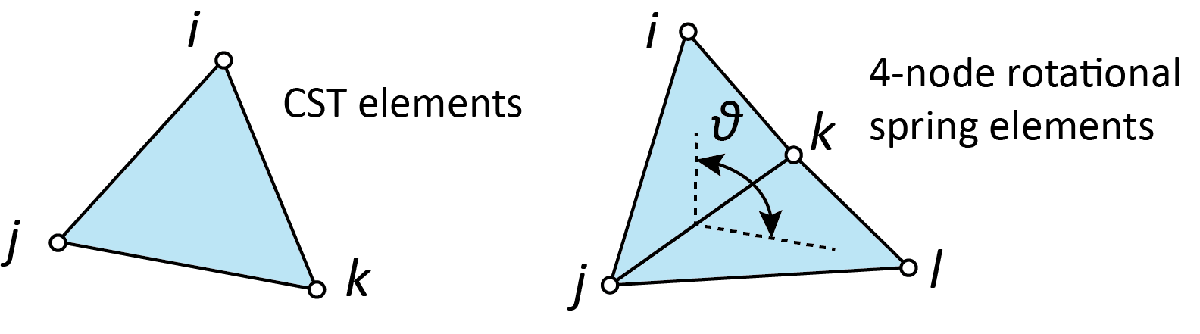

After defining the cst, we define the rotational springs. Every rotational spring has four node as shown in the above figure. Based on the four nodal coordinates (node i, j, k, and l), we can calcualte the $\theta \;$angle between the two triangles. This representation can capture the origami folding very well. A more detailed introduction of this element can be found in Section 09. 

% Springs for the panel bending
rotSpr.node_ijkl_mat=[1 2 4 5;
                      2 3 5 6;
                      7 4 8 5;
                      8 5 9 6];

% Springs for the crease folding
rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                      4 2 5 3;
                      3 5 6 9;
                      4 5 8 9;
                      2 4 5 8];

% Spring stiffness
rotSpr.rot_spr_K_vec=ones(8,1);
rotSpr.rot_spr_K_vec(1:4)=rotSpr.rot_spr_K_vec(1:4)*k_p;
rotSpr.rot_spr_K_vec(5:8)=rotSpr.rot_spr_K_vec(5:8)*k_f;

Finally, we plot the cst elements and the rotational spring elements for inspection. Based on the visual result, we know that the code is working well.

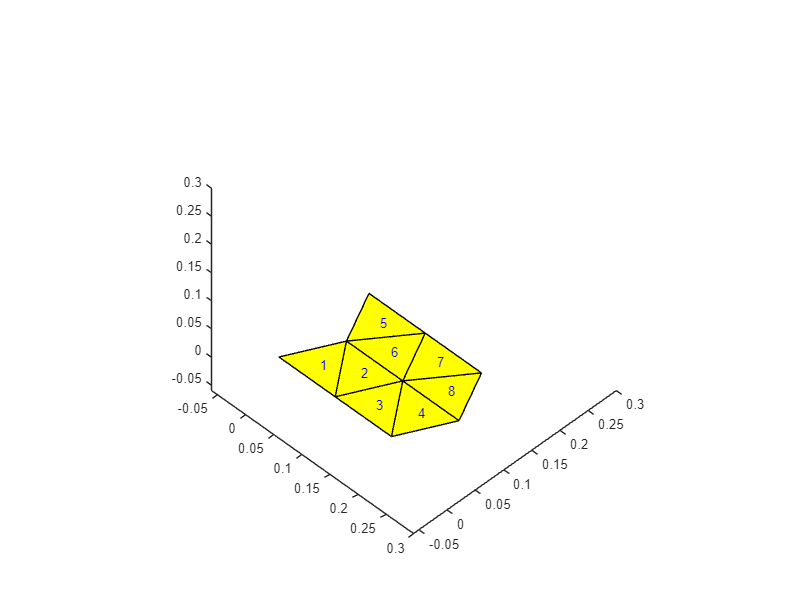

%Plot for investigation
assembly.Initialize_Assembly();
plots.Plot_Shape_CSTNumber();

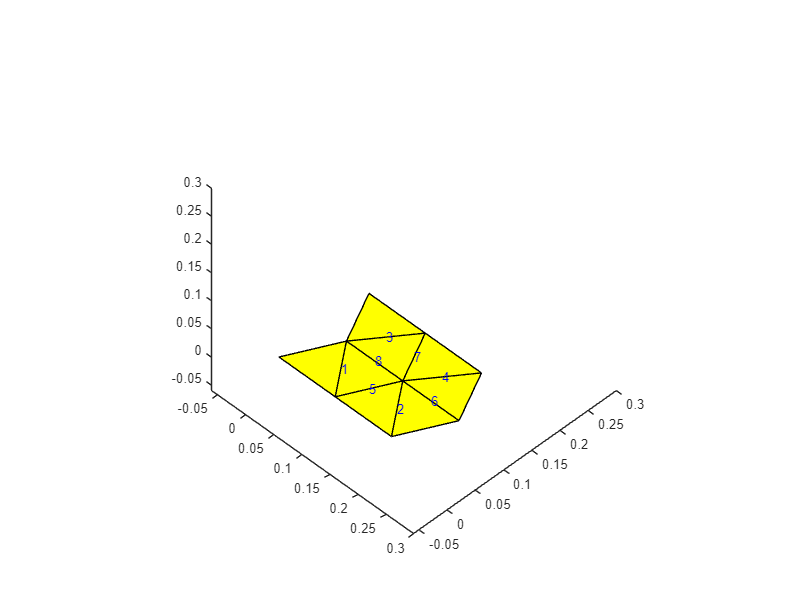

plots.Plot_Shape_SprNumber()

Here we use the Newton-Raphson solver for four-node spring self folding. We set up the folding such that the target folding angle is $0\ldotp 8\pi \;$ away from the flat. Here we define the folding angle at flat as 180 degree or $\phi =\pi \ldotp$ With this assumption, the mountain Fold is defined to be smaller than $\pi \;$and the valley folds are bigger than $\pi$. 

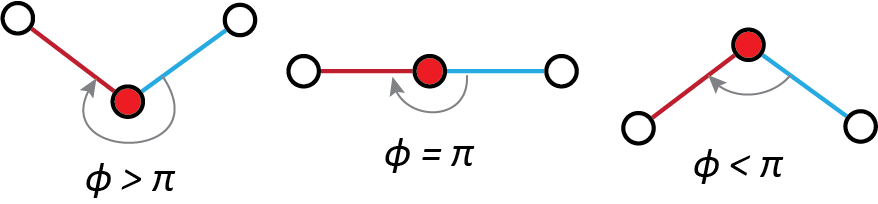

sf=Solver_NR_Folding_4N;
sf.assembly=assembly;
sf.supp=[1,1,1,1;
         2,1,1,1;
         4,1,1,1;];

% Define the target folding angle
foldAngle=0.8*pi;

% Please note that fold 8 is a mountain fold while 
% fold 5 6 7 are valley folds
sf.targetRot=assembly.rotSpr.theta_current_vec;
sf.targetRot(8)=sf.targetRot(8)-foldAngle;
sf.targetRot(5)=sf.targetRot(5)+foldAngle;
sf.targetRot(6)=sf.targetRot(6)+foldAngle;
sf.targetRot(7)=sf.targetRot(7)+foldAngle;

% Solver parameters
sf.increStep=50;
sf.tol=10^-6;
sf.iterMax=50;

After setting up the solver, we can solve for the folding history of this Miura origami unit. The deformed shape is nexted plotted.

Uhis=sf.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 2.362301e-05 
	Iteration = 2, R = 6.605244e+00 
	Iteration = 3, R = 1.537245e-02 
	Iteration = 4, R = 1.188171e-04 
	Iteration = 5, R = 4.604502e-06 
	Iteration = 6, R = 2.495683e-09 
Icrement = 2
	Iteration = 1, R = 2.362176e-05 
	Iteration = 2, R = 6.598263e+00 
	Iteration = 3, R = 1.536497e-02 
	Iteration = 4, R = 3.656984e-04 
	Iteration = 5, R = 1.563824e-04 
	Iteration = 6, R = 9.301446e-06 
	Iteration = 7, R = 5.436388e-07 
Icrement = 3
	Iteration = 1, R = 2.361800e-05 
	Iteration = 2, R = 6.602780e+00 
	Iteration = 3, R = 1.549591e-02 
	Iteration = 4, R = 1.572342e-04 
	Iteration = 5, R = 3.650310e-05 
	Iteration = 6, R = 1.331494e-07 
Icrement = 4
	Iteration = 1, R = 2.361180e-05 
	Iteration = 2, R = 6.604280e+00 
	Iteration = 3, R = 1.558798e-02 
	Iteration = 4, R = 2.344666e-04 
	Iteration = 5, R = 3.756106e-05 
	Iteration = 6, R = 9.160102e-07 
Icrement = 5
	Iteration = 1, R = 2.360300e-05 
	Iteration = 2, R = 6.6

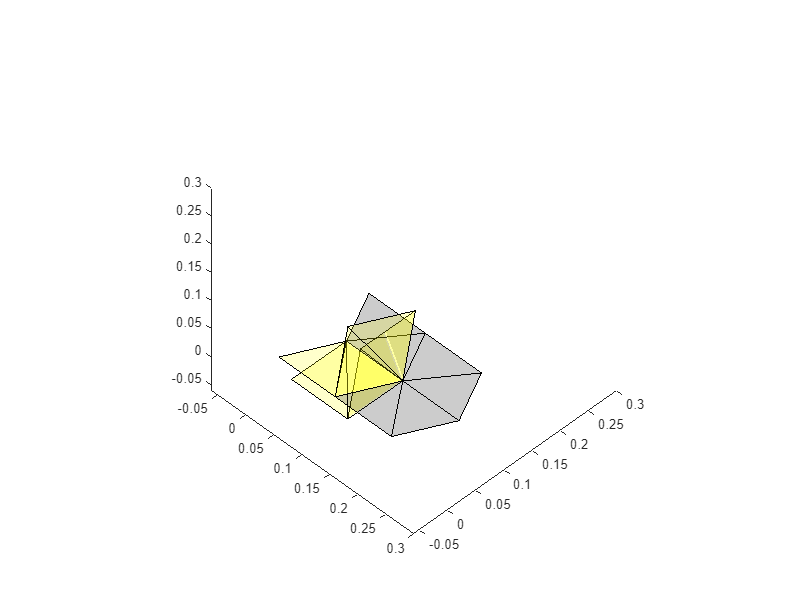

plots.Plot_DeformedShape(squeeze(Uhis(end,:,:)));

We also hope to generate an animation of the full deployment process. This is done with the following code. We can now check out the generated GIF figure for the animation. 

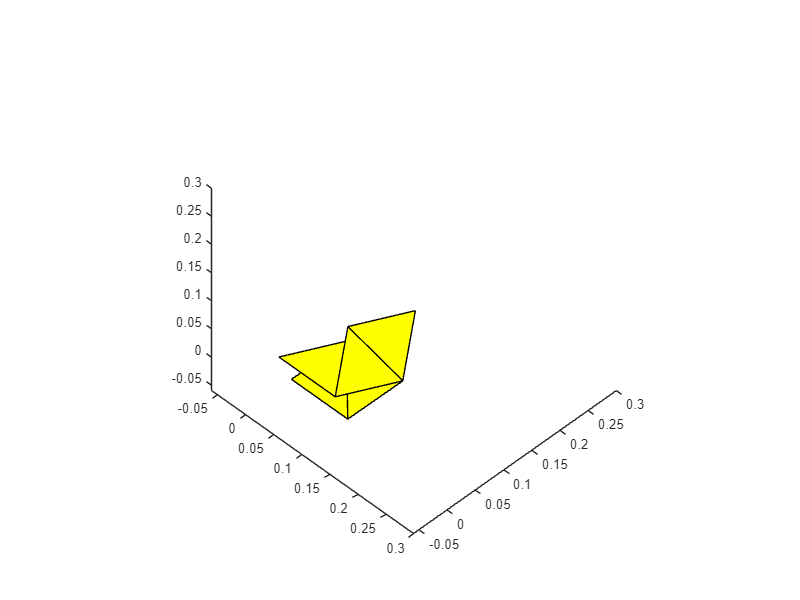

plots.fileName='Miura_Unit_Folding.gif';
plots.Plot_DeformedHis(Uhis);

The generated GIF is embeded here in the live script:

## 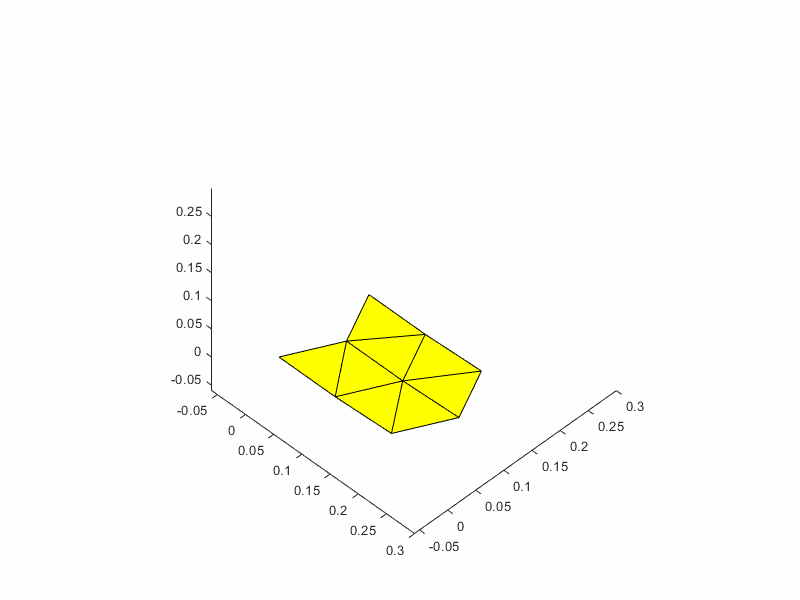

To practice, please consider further working out the following problems. 

**Problem 01**

Can you make a simulation of a full Miura origami sheet with 2*2 units?